## Create cylindrical grid and load data

%Center positions
c_x=93;
c_y=122;
pix_x=192;
pix_y=256;
ratio=pix_x/pix_y;

%Cylindrical GRID
phi_deg=-162:1:198; phi_rad=phi_deg*pi/180;
r=0.5:1:92.5;
z=ratio*(0.5-c_y:1:pix_y-c_y-0.5);
[phimesh,rmesh,zmesh]=ndgrid(phi_rad,r,z);

load('GMS_volumetric_polar_1deg_sm_2.mat','I_cyl'); % load (smoothed) raw data in the cyl grid

## Retrieve modulated rings in Cartesian coordinates

alpha_Fit=-0.135;
qmax_Fit=0.643;

%Cartesian coordinates of the four rings parametrized by their polar angle
[Qmod_111,Qmod_1m1m1,Qmod_m11m1,Qmod_m1m11]= Model_Modulated_rings(alpha_Fit,qmax_Fit);  

%transformation matrix
A1=[1/sqrt(2)*[1;-1;0],1/sqrt(6)*[1;1;-2],1/sqrt(3)*[1;1;1]];
A2=[1/sqrt(2)*[0;-1;1],-1/sqrt(6)*[2;1;1],1/sqrt(3)*[1;-1;-1]];
A3=[1/sqrt(2)*[1;0;-1],-1/sqrt(6)*[1;2;1],1/sqrt(3)*[-1;1;-1]];
A4=[-1/sqrt(2)*[1;-1;0],-1/sqrt(6)*[1;1;2],1/sqrt(3)*[-1;-1;1]];

## Test cylindrical data

The Experimental coordinate system is the following: [11-2], -[111], [1-10] (left-handed due to the CW rotation sense of omega)

special omega angles: 

0°: [11-2]

35.2°: [001] 

90°: [111]

125.2° [110]

160.5° [-1-11]

180° [-1-12]

from this on, the intensity should be periodic.

figure(15)
phi1=90+71

phi1 = 161

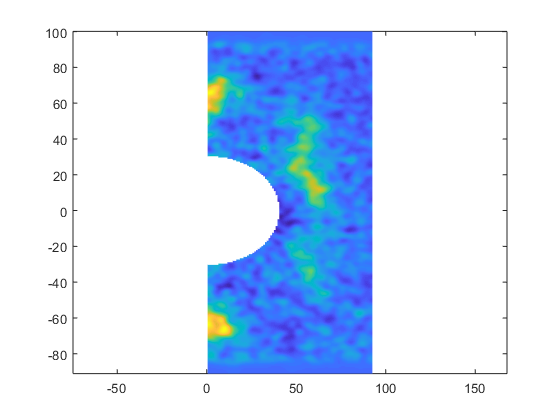

ind=phi1; %index of phi coordinate
cla
X=squeeze(rmesh(ind,:,:));
Y=squeeze(zmesh(ind,:,:));
I=squeeze(I_cyl(ind,:,:));


pcolor(X,Y,I); shading('interp')
hold on
axis equal

## Calculate q-rings in the experimental coordinate system

Retrieving the space curves parametrized in the rhombohedral frame and convert it to the experimental frame, using function get_chi_omega_fun.m 

alpha=-0.135;
omega_deg = linspace(0,360,361);

[omega_rad_1m1m1, chi_rad_1m1m1, phi, theta, Q_1m1m1] = get_chi_omega_fun(alpha, 1, omega_deg);
[omega_rad_m11m1, chi_rad_m11m1, ~, ~, Q_m11m1] = get_chi_omega_fun(alpha, 2, omega_deg);
[omega_rad_1m1m1, chi_rad_0_1m1m1, ~] = get_chi_omega_fun(0, 1, omega_deg);
[omega_rad_m11m1, chi_rad_0_m11m1, ~] = get_chi_omega_fun(0, 2, omega_deg);


### Plot the dependence of the azimuth angle on the DOM rotation angle \chi(\omega) 

Red curve: alpha=0 (GVS, no anisotropy)

Blue curve: alpha=-0.135 (GMS)

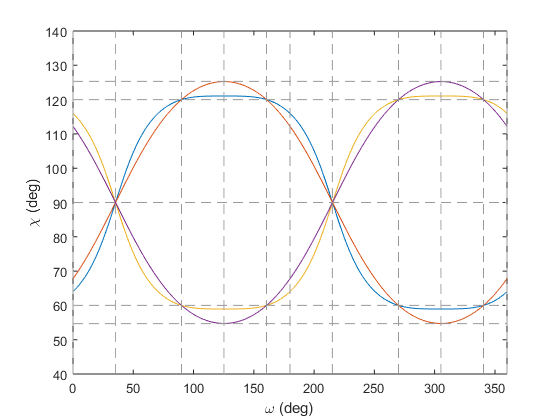

figure(20)
cla
plot(omega_deg, chi_rad_1m1m1*180/pi)
hold on
plot(omega_deg, chi_rad_0_1m1m1*180/pi)

plot(omega_deg, chi_rad_m11m1*180/pi)
plot(omega_deg, chi_rad_0_m11m1*180/pi)


x = [0, 35.2, 90, 90+35.2, 180-19.5, 180, 180+35.2, 270, 270+35.2, 360-19.5, 360];
y = [54.7, 60, 90, 120, 180-54.7];
for i=1:length(x)
    line([x(i),x(i)],[40,140],'LineStyle', '--', 'color', [0.6,0.6,0.6] , 'LineWidth', 0.5)
end
for i=1:length(y)
    line([0,360],[y(i),y(i)],'LineStyle', '--', 'color', [0.6,0.6,0.6], 'LineWidth', 0.5)
end

xlim([0, 360])
xlabel('\omega (deg)')
ylabel('\chi (deg)')

### Plot the q-ring in three dimension as parametrized by the omega angle (0:1:360)

Note that the reference frame is now X=[11-2], Y=[111], Z=[1-10], as in the experiment

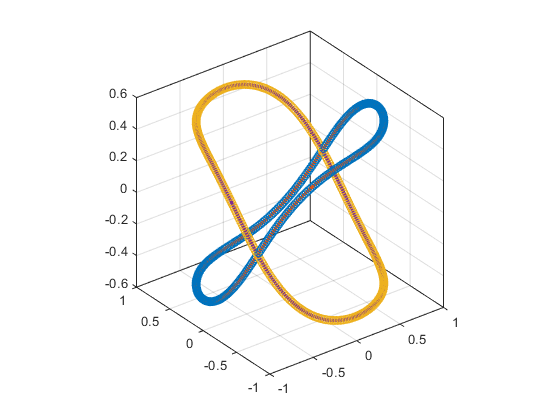

figure(21)
cla

QX_1m1m1=sin(chi_rad_1m1m1).*cos(omega_rad_1m1m1);
QY_1m1m1=sin(chi_rad_1m1m1).*sin(omega_rad_1m1m1);
QZ_1m1m1=cos(chi_rad_1m1m1);

QX_m11m1=sin(chi_rad_m11m1).*cos(omega_rad_m11m1);
QY_m11m1=sin(chi_rad_m11m1).*sin(omega_rad_m11m1);
QZ_m11m1=cos(chi_rad_m11m1);


scatter3(Q_1m1m1(1,:), Q_1m1m1(2,:), Q_1m1m1(3,:))
hold on
plot3(QX_1m1m1, QY_1m1m1, QZ_1m1m1, 'linewidth', 2.5)

scatter3(Q_m11m1(1,:), Q_m11m1(2,:), Q_m11m1(3,:))
hold on
plot3(QX_m11m1, QY_m11m1, QZ_m11m1, 'linewidth', 2.5)


axis square
box on

The blue curve plots the Q vectors directly in Cartesian coordinates, while the red curve is calculated back to spherical coordinates and is parametrized by omega.

## Plot the azimuth angle over the experimental data

figure(22)
cla
phi1=110

phi1 = 110

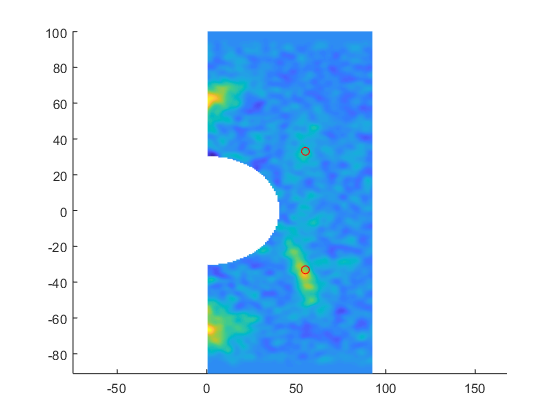

ind=phi1; %index of phi coordinate
cla
X=squeeze(rmesh(ind,:,:));
Y=squeeze(zmesh(ind,:,:));
I=squeeze(I_cyl(ind,:,:));
hold on

pcolor(X,Y,I); shading('interp')
plot(sin(chi_rad_1m1m1(phi1))*qmax_Fit*100, cos(chi_rad_1m1m1(phi1))*qmax_Fit*100, 'ro')
plot(sin(chi_rad_m11m1(phi1))*qmax_Fit*100, cos(chi_rad_m11m1(phi1))*qmax_Fit*100, 'ro')
hold on
axis equal

## Extract intentsity along the rings

### Check the intensity in special planes

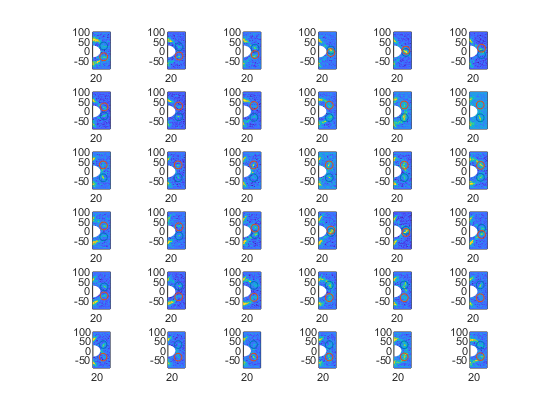

phi1=1:10:351;
figure(153)
for i=1:36
    ind=phi1(i); %index of phi coordinate
    r=20;
    
    
    subplot(6,6,i)
    
    cla
    X=squeeze(rmesh(ind,:,:));
    Y=squeeze(zmesh(ind,:,:));
    I=squeeze(I_cyl(ind,:,:));
    
    x0_1 = sin(chi_rad_1m1m1(phi1(i)))*qmax_Fit*100;
    y0_1 = cos(chi_rad_1m1m1(phi1(i)))*qmax_Fit*100;
    x0_2 = sin(chi_rad_m11m1(phi1(i)))*qmax_Fit*100;
    y0_2 = cos(chi_rad_m11m1(phi1(i)))*qmax_Fit*100;
    
    pcolor(X, Y, I); shading('interp')
    hold on
    circle(x0_1, y0_1, r);
    circle(x0_2, y0_2, r);

    axis equal
    axis tight
    

end


phi1=[1, 36, 91, 126, 181-19, 181];
planes = ['(11-2)', '(001)', '(111)', '(110)', '(-1-10)']

planes = '(11-2)(001)(111)(110)(-1-10)'

Int1 = 5.8621e+03

Int1 = 1.0918e+03

Int1 = 8.9471e+03

Int1 = 3.0044e+03

Int1 = 8.9804e+03

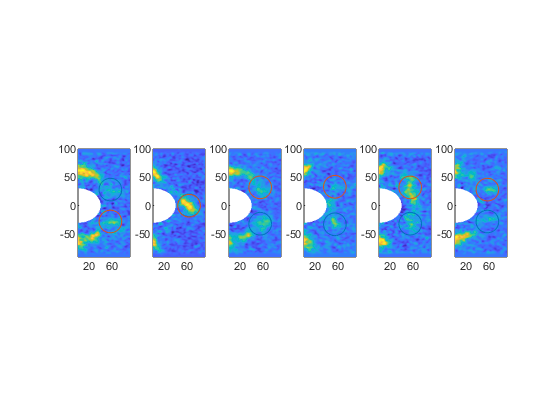

Int1 = 3.8171e+03

figure(32153)
for i=1:6
    ind=phi1(i); %index of phi coordinate
    r=20;
    
    
    subplot(1,6,i)
    
    cla
    X=squeeze(rmesh(ind,:,:));
    Y=squeeze(zmesh(ind,:,:));
    I=squeeze(I_cyl(ind,:,:));
    
    x0_1 = sin(chi_rad_1m1m1(phi1(i)))*qmax_Fit*100;
    y0_1 = cos(chi_rad_1m1m1(phi1(i)))*qmax_Fit*100;
    x0_2 = sin(chi_rad_m11m1(phi1(i)))*qmax_Fit*100;
    y0_2 = cos(chi_rad_m11m1(phi1(i)))*qmax_Fit*100;
    
    pcolor(X, Y, I); shading('interp')
    hold on
    circle(x0_1, y0_1, r);
    circle(x0_2, y0_2, r);

    axis equal
    axis tight
    
    mask1 = (X-x0_1).^2+(Y-y0_1).^2 <r^2;
    mask2 = (X-x0_2).^2+(Y-y0_2).^2 <r^2;
    mask12 = logical(mask1 .* mask2);
    
    Int1 = sum(I(mask))+sum(I(mask2))-sum(I(mask12))

end

### Check intensity along all scattering planes

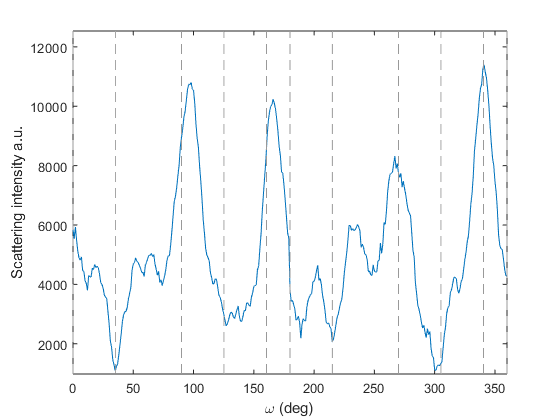

Int = zeros(1,360);
omega = 0:1:360;
plot_fns = 0;

for phi1=1:361
    ind=phi1; %index of phi coordinate
    X=squeeze(rmesh(ind,:,:));
    Y=squeeze(zmesh(ind,:,:));
    I=squeeze(I_cyl(ind,:,:));

    x0_1 = sin(chi_rad_1m1m1(phi1))*qmax_Fit*100;
    y0_1 = cos(chi_rad_1m1m1(phi1))*qmax_Fit*100;
    x0_2 = sin(chi_rad_m11m1(phi1))*qmax_Fit*100;
    y0_2 = cos(chi_rad_m11m1(phi1))*qmax_Fit*100;
  
    mask1 = (X-x0_1).^2+(Y-y0_1).^2 <r^2;
    mask2 = (X-x0_2).^2+(Y-y0_2).^2 <r^2;
    mask12 = (mask1 & mask2);

    Int(phi1) = sum(I(mask))+sum(I(mask2))-sum(I(mask12));
end

figure(312)
plot(omega, Int)

x = [0, 35.2, 90, 90+35.2, 180-19.5, 180, 180+35.2, 270, 270+35.2, 360-19.5, 360];
for i=1:length(x)
    line([x(i),x(i)],[0.9*min(Int),1.1*max(Int)],'LineStyle', '--', 'color', [0.6,0.6,0.6] , 'LineWidth', 0.5)
end
ylim([0.9*min(Int),1.1*max(Int)])
xlim([0, 360])
xlabel('\omega (deg)')
ylabel('Scattering intensity a.u.')

## Plot the ring in the Lab coordinate system

Blue circles: q-vectors transformed to Lab system

Red circles: ring parametrized by omega, transformed to the Lab system

Green line: q-vectors retrieved from the original phi parametrization, transformed to the Lab system

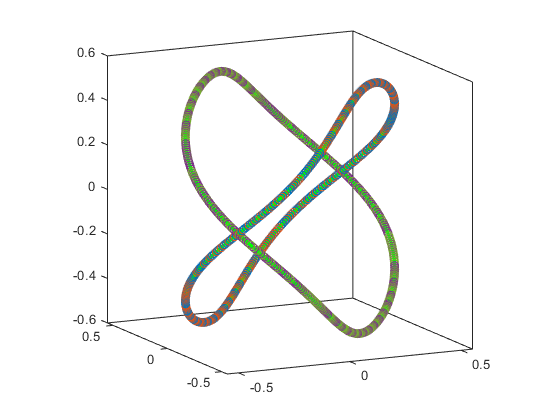

% transformation
A1m10 = [1/sqrt(3), 1/sqrt(6), 1/sqrt(2); 1/sqrt(3), 1/sqrt(6), -1/sqrt(2); 1/sqrt(3), -2/sqrt(6),0];

Q_lab_1m1m1 = A1m10*Q_1m1m1*qmax_Fit;
Q_lab2_1m1m1 = A1m10*[QX_1m1m1; QY_1m1m1; QZ_1m1m1]*qmax_Fit;

Q_lab_m11m1 = A1m10*Q_m11m1*qmax_Fit;
Q_lab2_m11m1 = A1m10*[QX_m11m1; QY_m11m1; QZ_m11m1]*qmax_Fit;

figure(23)
cla

hold on
scatter3(Q_lab_1m1m1(1,:), Q_lab_1m1m1(2,:), Q_lab_1m1m1(3,:))
scatter3(Q_lab2_1m1m1(1,:), Q_lab2_1m1m1(2,:), Q_lab2_1m1m1(3,:))
plot3(Qmod_1m1m1(:,1),Qmod_1m1m1(:,2),Qmod_1m1m1(:,3),'linewidth',2.5,'color','g')


scatter3(Q_lab_m11m1(1,:), Q_lab_m11m1(2,:), Q_lab_m11m1(3,:))
scatter3(Q_lab2_m11m1(1,:), Q_lab2_m11m1(2,:), Q_lab2_m11m1(3,:))
plot3(Qmod_m11m1(:,1),Qmod_m11m1(:,2),Qmod_m11m1(:,3),'linewidth',2.5,'color','g')
box on
axis square
view(-26,12)

All three curves overlap properly.

## Plot the 3D distribution

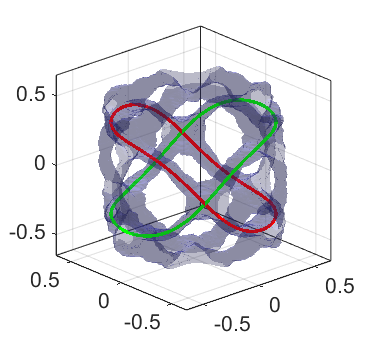

load('Cartesian_mesh_Lab.mat') %load standard base mesh
load('GMS_intensity_fullsymmetrized.mat','I_av') %load fully symmetrized data


I_fit=I_av; %select data to fit
I_fit(isnan(I_fit))=0;

thr_low=4;
ind=find(I_fit>thr_low);
[K,L,M]=ind2sub([171,171,171],ind);

col=[0.4,0.4,1]; %blue
alph=0.3;
thr=3.6; %Intensity threshold for visualization : best option: 3.6

figure(52)
wx=9.9;
wy=9.22;
cla
hold on
Plot_RST(Xc,Yc,Zc,I_av,thr,col,alph);
plot3(QY_1m1m1*qmax_Fit, QX_1m1m1*qmax_Fit, QZ_1m1m1*qmax_Fit,'linewidth',2.5,'color','r')
plot3(QY_m11m1*qmax_Fit, QX_m11m1*qmax_Fit, QZ_m11m1*qmax_Fit,'linewidth',2.5,'color','g')
%plot3(Qmod_1m1m1(:,1),Qmod_1m1m1(:,2),Qmod_1m1m1(:,3),'linewidth',2.5,'color','r')
%plot3(Qmod_m11m1(:,1),Qmod_m11m1(:,2),Qmod_m11m1(:,3),'linewidth',2.5,'color','b')
%plot3(Qmod_m1m11(:,1),Qmod_m1m11(:,2),Qmod_m1m11(:,3),'linewidth',2.5,'color','g')
set(gcf,'Units','centimeters');
set(gcf, 'Position', [1.1007 1.7357 wx wy]);
view(100,13);
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid on

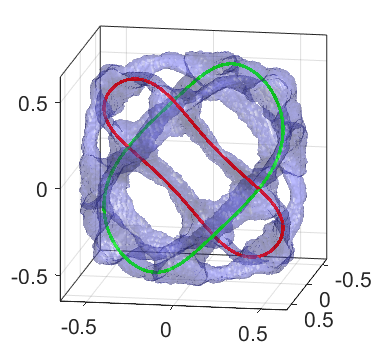


load('Cartesian_mesh_Lab.mat') %load standard base mesh
load('GMS_intensity_fullsymmetrized.mat','I_av') %load fully symmetrized data


I_fit=I_av; %select data to fit
I_fit(isnan(I_fit))=0;

thr_low=4;
ind=find(I_fit>thr_low);
[K,L,M]=ind2sub([171,171,171],ind);
Qx=squeeze(Xc(1,L,1)); %ndgrid: 1st index K, meshgrid: 2nd index K
Qy=squeeze(Yc(K,1,1)); %ndgrid: 2nd index L, meshgrid: 1st index L
Qz=squeeze(Zc(1,1,M));

T=[1/sqrt(6)*[1;1;-2],1/sqrt(3)*[1;1;1],1/sqrt(2)*[1;-1;0]];
A=[Xc(:),Yc(:),Zc(:)]*T';
Xt=reshape(A(:,1),size(Xc));
Yt=reshape(A(:,2),size(Yc));
Zt=reshape(A(:,3),size(Zc));

Q_1m1m1=[Qx',Qy,Qz];

Qexp=Q_1m1m1*T';
W=I_fit(ind); %weights of the experimental q-vectors, i.e. SANS counts at the given vectors


col=[0.4,0.4,1]; %blue
alpha=0.3;
thr=3.6; %Intensity threshold for visualization : best option: 3.6


figure(52)
wx=9.9;
wy=9.22;
cla
hold on
Plot_RST(Xt,Yt,Zt,I_av,thr,col,alpha);
plot3(Q_lab2_1m1m1(1,:), Q_lab2_1m1m1(2,:), Q_lab2_1m1m1(3,:),'linewidth',2.5,'color','r')
plot3(Q_lab2_m11m1(1,:), Q_lab2_m11m1(2,:), Q_lab2_m11m1(3,:),'linewidth',2.5,'color','g')
%plot3(Qmod_1m1m1(:,1),Qmod_1m1m1(:,2),Qmod_1m1m1(:,3),'linewidth',2.5,'color','r')
%plot3(Qmod_m11m1(:,1),Qmod_m11m1(:,2),Qmod_m11m1(:,3),'linewidth',2.5,'color','b')
%plot3(Qmod_m1m11(:,1),Qmod_m1m11(:,2),Qmod_m1m11(:,3),'linewidth',2.5,'color','g')
set(gcf,'Units','centimeters');
set(gcf, 'Position', [1.1007 1.7357 wx wy]);
view(100,13);
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])
axis square
grid on

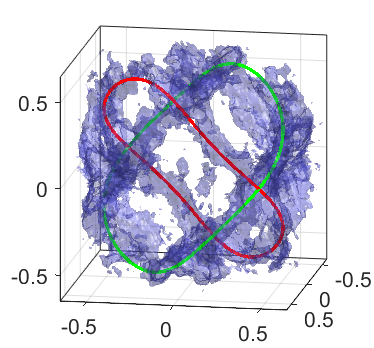

load('GMS_intensity_raw.mat','I_cart_cartint') %load raw data

% Try different alpha parameters
alpha=-0.135;

[omega_rad_1m1m1, chi_rad_1m1m1, ~] = get_chi_omega_fun(alpha);
QX_1m1m1=sin(chi_rad_1m1m1).*cos(omega_rad_1m1m1);
QY_1m1m1=sin(chi_rad_1m1m1).*sin(omega_rad_1m1m1);
QZ_1m1m1=cos(chi_rad_1m1m1);
Q_lab2_1m1m1 = A1m10*[QX_1m1m1; QY_1m1m1; QZ_1m1m1]*qmax_Fit;


I_fit=I_cart_cartint; %select data to fit
I_fit(isnan(I_fit))=0;

thr_low=3.6;
ind=find(I_fit>thr_low);
[K,L,M]=ind2sub([171,171,171],ind);
Qx=squeeze(Xc(1,L,1)); %ndgrid: 1st index K, meshgrid: 2nd index K
Qy=squeeze(Yc(K,1,1)); %ndgrid: 2nd index L, meshgrid: 1st index L
Qz=squeeze(Zc(1,1,M));

T=[1/sqrt(6)*[1;1;-2],1/sqrt(3)*[1;1;1],1/sqrt(2)*[1;-1;0]];
A=[Xc(:),Yc(:),Zc(:)]*T';
Xt=reshape(A(:,1),size(Xc));
Yt=reshape(A(:,2),size(Yc));
Zt=reshape(A(:,3),size(Zc));

Q_1m1m1=[Qx',Qy,Qz];

Qexp=Q_1m1m1*T';
W=I_fit(ind); %weights of the experimental q-vectors, i.e. SANS counts at the given vectors


col=[0.4,0.4,1]; %blue
alpha=0.3;
thr=3.6; %Intensity threshold for visualization : best option: 3.6

figure(53)
wx=9.9;
wy=9.22;
cla
hold on
Plot_RST(Xt,Yt,Zt,I_cart_cartint,thr,col,alpha);
plot3(Q_lab2_1m1m1(1,:), Q_lab2_1m1m1(2,:), Q_lab2_1m1m1(3,:),'linewidth',2.5,'color','r')
plot3(Q_lab2_m11m1(1,:), Q_lab2_m11m1(2,:), Q_lab2_m11m1(3,:),'linewidth',2.5,'color','g')
%plot3(Qmod_m11m1(:,1),Qmod_m11m1(:,2),Qmod_m11m1(:,3),'linewidth',2.5,'color','b')
%plot3(Qmod_m1m11(:,1),Qmod_m1m11(:,2),Qmod_m1m11(:,3),'linewidth',2.5,'color','g')
set(gcf,'Units','centimeters');
set(gcf, 'Position', [1.1007 1.7357 wx wy]);
view(100,13);
lim=0.65;
xlim([-lim,lim])
ylim([-lim,lim])
zlim([-lim,lim])

axis square
grid on

function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit);
    hold off
end